clc;clear;
H_p = deg2rad(0) % Heading of the plane

H_p = 0

H_PG = deg2rad(360-5) % Heading Plane GPS offsett

H_PG = 6.1959

V_o = 0.2 % speed offset airspeed gps

V_o = 0.2000


V_P = 5.5

V_P = 5.5000


V_PA = V_P*exp(i*H_p) % Airspeed

V_PA = 5.5000

V_PG = (V_P+V_o)*exp(i*H_PG) % Groundspeed

V_PG = 5.6783 - 0.4968i



V_AG = V_PG-V_PA

V_AG = 0.1783 - 0.4968i

Wind_angle = rad2deg(angle(V_AG));
if Wind_angle < 0
    Wind_angle= 360-abs(Wind_angle)
    Wind_ampl = abs(V_AG)
else
    Wind_angle
    Wind_ampl = abs(V_AG)
end

Wind_angle = 289.7444

Wind_ampl = 0.5278

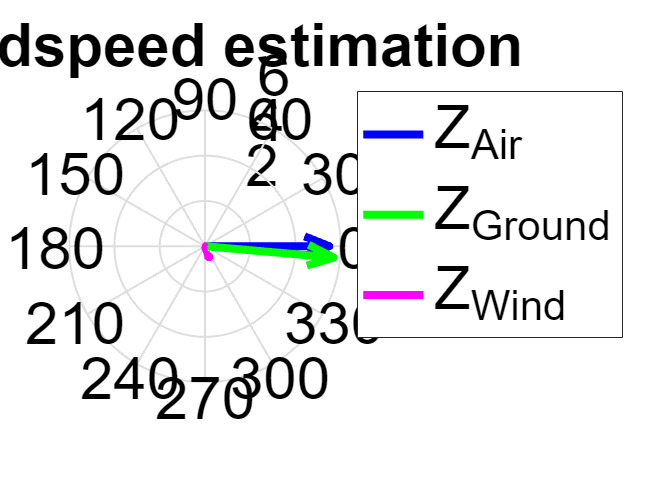

LineWidth = 4;
FontSize = 30;

figure
h1 = compass(real(V_PA), imag(V_PA), 'b');
hold on;
h2 = compass(real(V_PG), imag(V_PG), 'g');
h3 = compass(real(V_AG), imag(V_AG), 'm');
set(h1, 'LineWidth', LineWidth);
set(h2, 'LineWidth', LineWidth);
set(h3, 'LineWidth', LineWidth);
title('Windspeed estimation')
lgd=legend({"Z_{Air}","Z_{Ground}","Z_{Wind}"},'Location','northeastoutside');
fontsize(lgd,FontSize,'points');
fontsize(gca, FontSize,'points');
hold off;

clc;clear;
H_p = deg2rad(0) % Heading of the plane

H_p = 0

H_PG = deg2rad(360-5) % Heading Plane GPS offsett

H_PG = 6.1959

V_o = -8 % speed offset airspeed gps

V_o = -8


V_P = 10

V_P = 10


V_PA = V_P*exp(i*H_p)

V_PA = 10

V_PG = (V_P+V_o)*exp(i*H_PG)

V_PG = 1.9924 - 0.1743i


V_AG = V_PG-V_PA

V_AG = -8.0076 - 0.1743i


Wind_angle = rad2deg(angle(V_AG));
if Wind_angle < 0
    Wind_angle= 360-abs(Wind_angle)
    Wind_ampl = abs(V_AG)
else
    Wind_angle
    Wind_ampl = abs(V_AG)
end

Wind_angle = 181.2470

Wind_ampl = 8.0095

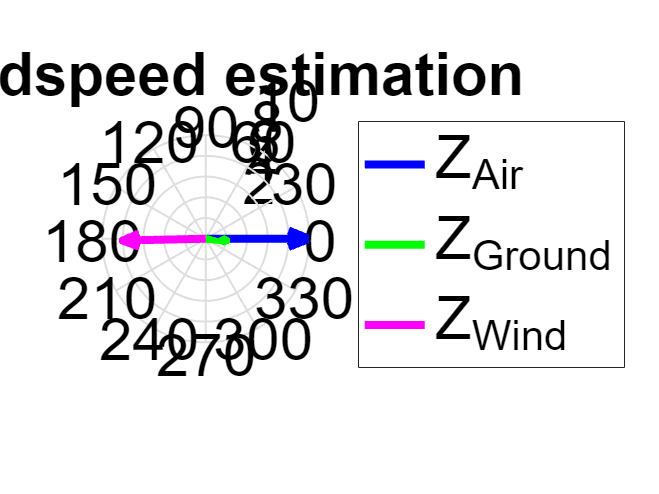



LineWidth = 4;
FontSize = 30;

figure
h1=compass(real(V_PA),imag(V_PA),"b");
hold on;
h2=compass(real(V_PG),imag(V_PG),"g");
h3=compass(real(V_AG),imag(V_AG),"m");
set(h1, 'LineWidth', LineWidth);
set(h2, 'LineWidth', LineWidth);
set(h3, 'LineWidth', LineWidth);
title('Windspeed estimation');
lgd=legend({"Z_{Air}","Z_{Ground}","Z_{Wind}"},'Location','northeastoutside');
fontsize(lgd,FontSize,'points');
fontsize(gca, FontSize,'points');
hold off;